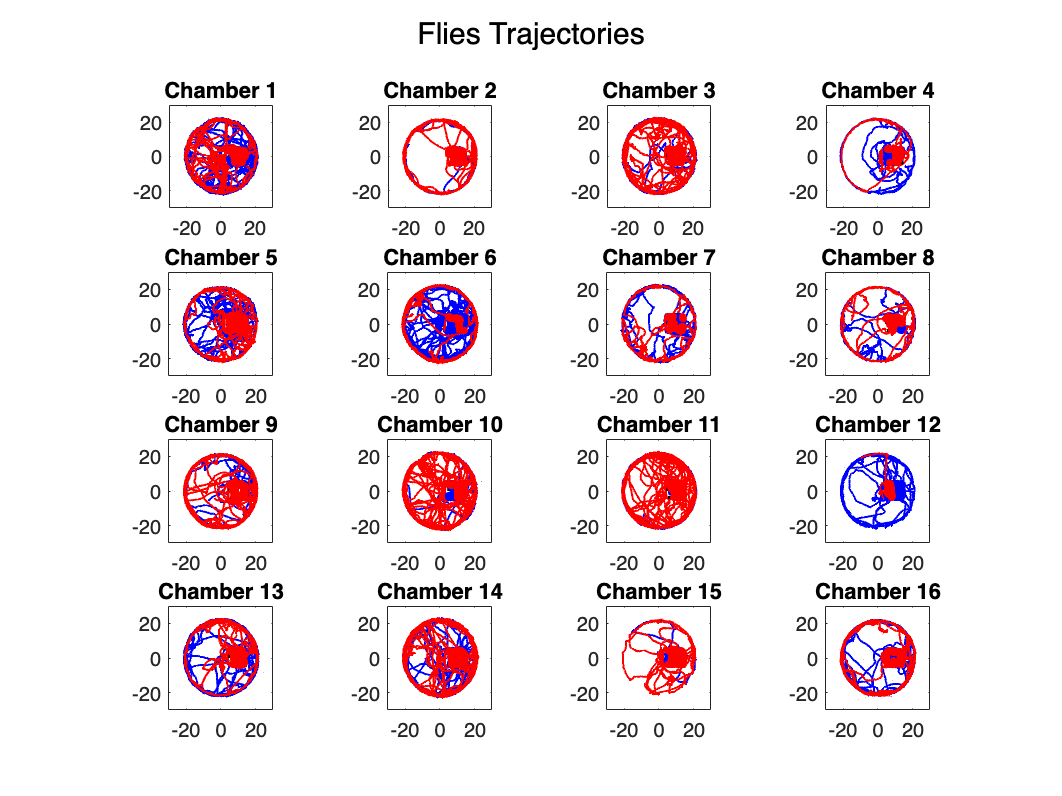

% IDs of individuals to analyze (two flies per chamber) in the tunnel,
% create before a trxall data
individuals_IDs = 1:32;  % 32 flies, 16 chambers (two flies per chamber)

% Define the rectangular ROI (bounds)

roi_x_min = min(14.01, 5.06);  % Ensure x_min is smaller
roi_x_max = max(14.01, 5.06);  % Ensure x_max is larger
roi_y_min = min(-3.76, 4.37);  % Ensure y_min is smaller
roi_y_max = max(-3.76, 4.37);  % Ensure y_max is larger

% Number of chambers (pairs of flies)
num_chambers = length(individuals_IDs) / 2;

% Initialize variable to store time spent in ROI for each fly
time_in_roi = zeros(2, num_chambers);  % Rows: fly 1 & fly 2, Columns: chambers

% Plot the trajectories for each pair with ROI marked
figure;
for i = 1:num_chambers
    % Get the IDs for the pair of flies in the current chamber
    fly1_id = individuals_IDs(2*i - 1);
    fly2_id = individuals_IDs(2*i);
    
    % Create a subplot for the current chamber
    subplot(4, 4, i);  
    
    % Fly 1: Access its x_mm and y_mm positions
    posx1 = trxall(fly1_id).x_mm;  
    posy1 = trxall(fly1_id).y_mm;
    
    % Fly 2: Access its x_mm and y_mm positions
    posx2 = trxall(fly2_id).x_mm;  
    posy2 = trxall(fly2_id).y_mm;
    
    % Plot the trajectory for Fly 1
    plot(posx1, posy1, 'b-', 'LineWidth', 1);  % Blue for Fly 1
    hold on;
    
    % Plot the trajectory for Fly 2
    plot(posx2, posy2, 'r-', 'LineWidth', 1);  % Red for Fly 2
    
    % Plot the ROI as a red rectangle
    rectangle('Position', [roi_x_min, roi_y_min, roi_x_max - roi_x_min, roi_y_max - roi_y_min], ...
              'EdgeColor', 'k', 'LineWidth', 1.5, 'LineStyle', '--');
    
    % Highlight trajectory points inside the ROI for Fly 1
    in_roi1 = (posx1 >= roi_x_min & posx1 <= roi_x_max) & (posy1 >= roi_y_min & posy1 <= roi_y_max);
    plot(posx1(in_roi1), posy1(in_roi1), 'bo', 'MarkerSize', 3, 'MarkerFaceColor', 'b');  % Blue points
    
    % Highlight trajectory points inside the ROI for Fly 2
    in_roi2 = (posx2 >= roi_x_min & posx2 <= roi_x_max) & (posy2 >= roi_y_min & posy2 <= roi_y_max);
    plot(posx2(in_roi2), posy2(in_roi2), 'ro', 'MarkerSize', 3, 'MarkerFaceColor', 'r');  % Red points
    
    % Calculate the time spent in the ROI for Fly 1
    timestamps1 = trxall(fly1_id).timestamps;  % Adjust field name if needed
    if sum(in_roi1) > 1
        time_in_roi(1, i) = sum(diff(timestamps1(in_roi1)));  % Sum durations
    else
        time_in_roi(1, i) = 0;  % No time spent in ROI
    end
    
    % Calculate the time spent in the ROI for Fly 2
    timestamps2 = trxall(fly2_id).timestamps;  % Adjust field name if needed
    if sum(in_roi2) > 1
        time_in_roi(2, i) = sum(diff(timestamps2(in_roi2)));  % Sum durations
    else
        time_in_roi(2, i) = 0;  % No time spent in ROI
    end
    
    % Title for each subplot
    title(['Chamber ', num2str(i)]);
    axis equal;  % Maintain aspect ratio
    xlim([-30, 30]);  % Adjust based on arena size
    ylim([-30, 30]);
    hold off;
end
sgtitle('Flies Trajectories');

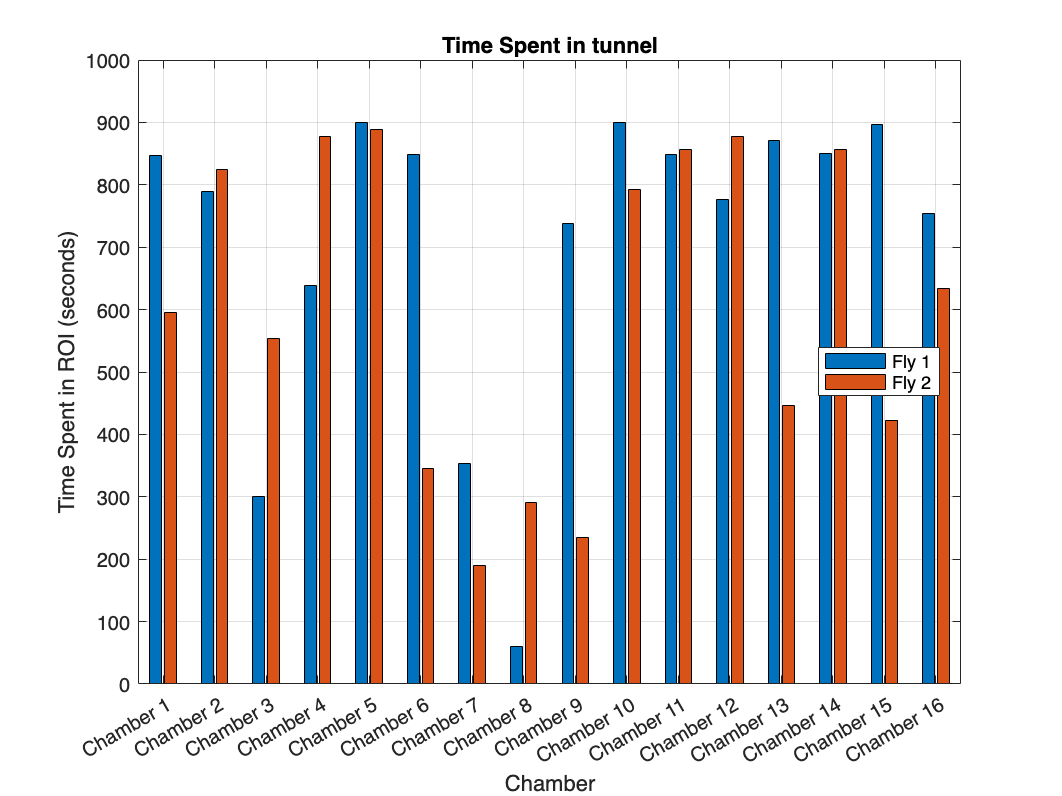


% Plot histogram of time spent in ROI for each fly
figure;
bar(time_in_roi', 'grouped');  % Grouped bar plot for Fly 1 and Fly 2
xticks(1:num_chambers);
xticklabels(arrayfun(@(x) ['Chamber ', num2str(x)], 1:num_chambers, 'UniformOutput', false));  % Label bars with chamber numbers
xlabel('Chamber');
ylabel('Time Spent in ROI (seconds)');
legend({'Fly 1', 'Fly 2'}, 'Location', 'best');
title('Time Spent in tunnel');
grid on;